# Зачем нужны матрицы

### Будем решать следующую задачу: 

### Как, имея таблицу данных с результатами измерения разных свойств, например, таблицу трендов по времени для свойств керамики, вытащенных за некоторый период времени, понять какие из свойств являются "линейно" коррелированными. 

Нужно ли мерить диэлектрическую постоянную, плотность и т.д. или достаточно скорости ультразвука ? ;)

## PCA - principal component analysis (анализ главных компонент)

PCA - способ анализа степени "независимости" столбцов матрицы. Позволяет понять есть ли среди данных "лишние", то есть не несущие информации, понять как нужно преобразовать исходные данные, чтобы они были максимально линейно независимыми. Позволяет уменьшить размерность данных. 

Применяется во многих разделах анализа данных, таких как, классификация, сжатие  и распознавание изображений, корреляционный анализ и др. Часто используется в машинном обучении, когда надо "прорядить" исходные данные обучающей выборки для нейронных сетей.

## Немного о матрицах.

#### Матрциа A - это:

- Упорядоченная коллекция чисел: $A(i,j)$ => индексирование (get_index, set_index)

- Упорядоченная коллекция вектор-столбцов: $A = [\vec{a_1},...,\vec{a_i},...,\vec{a_m}]$, $A(:,i)=\vec{a_i}$ => итерирование по столбцам матрицы в цикле

- Оператор линейного преобразования векторов, символ  $[A]$ - обозначает "действие" матрицы: $A\vec{b} = \vec{c}$ <=> подействовав матрицей $A$ на вектор $\vec{b}$ мы преобразовали его в вектор $\vec{c}$ 

- Совокупность $m$ вектор-столбцов (в каждом из которых $N$ координат) $A = [\vec{a_1},...,\vec{a_i},...,\vec{a_m}]$  - это линейное подпространство векторного пространства $R^N$ всех векторов размером $N$, обозначается как $span\{A\}$

Сингулярная матрица - матрица,  у которой колонки (или строки) являются зависимыми (либо равными нулю), то есть могут быть выражены как линейная комбинация других строк (колонок) этой же матрицы. 

Ранг матрицы  - количество ее линейно-независимых столбцов (строк)

Для сингулярной матрицы $A$размером $ [N\times M] $, размерность линейного подпространства  ее столбцов $span\{A\}$  меньше размерности линейного пространства $R^N$.

#### Как понять насколько сильно отличаются два вектора друг от друга?

Косинус угла между ними!

Косинус угла между двумя векторами:

$cos( \alpha) =\frac  {\vec a \cdot \vec b } {|\vec a | |\vec b |} =\hat a \cdot\frac  {\vec b } { |\vec b |} =\hat{a}^T \frac  {\vec b } { |\vec b |} $                                                                                                                                                            (*)

$\hat a$ - единичный вектор, направленный вдоль $\vec a
$

Чем меньше косинус угла между векторами, тем они больше друг от друга отличаются (для ортогональных векторов он равен нулю), чем ближе косинус (по модулю)   к единице, тем  более "похожи" вектора друг на друга, так как $cos( \alpha) =\frac  {\vec a \cdot \vec b } {|\vec a | |\vec b |}$

#### Проекция вектора на вектор

У вектора $\vec{b}$ есть зависимая от $\vec{a}$ компонента $\vec{b_{|| \vec{a}} }$, то есть та, которая может быть получена путем умножения $\vec{a}$ на число  и полностью независимая компонента $ \vec{b}_{\perp\vec{a}}}$ ортогональная вектору  $\vec{a}$.


$$\vec{b}=\vec{b_{|| \vec{a}} } + \vec{b}_{\perp\vec{a}}}$$


$\vec{b_{|| \vec{a}} }=\hat{a}|\vec{b}|cos(\alpha)=\hat{a} |\vec{b}| \hat{a}\cdot \frac  { \vec b } {|\vec b |}= \hat{a}( \hat{a}^T\vec{b})$ - вектор проекции вектора $\vec{b}$ на направление вектора $\vec{a}$ - показывает зависимую от $\vec{a}$ долю вектора $\vec{b}$ 

$\vec{b}_{\perp\vec{a}}=\vec{b} - \vec{b_{|| \vec{a}} } =\vec{b} - \hat{a}( \hat{a}^T\vec{b})$ - характеризует независимую от  вектора $\vec{a}$ составляющую вектора  $\vec{b}$                                     (**)

clearvars
a_vec = rand(2,1) % генерим случайный вектор на плоскости

% Проекция веткоров 
R =[78.511;0.73] % координаты вектора в сферической системе координат 
% угол - модуль
ang = deg2rad(R(1)); %угол вектора
module = R(2);% модуль вектора
b_vect = [module*cos(ang);module*sin(ang)];
a_hat = a_vec/norm(a_vec) %- единичный вектор вдоль а 
b_par = a_hat*(transpose(a_hat)*b_vect) % проекция вектора b на вектор а
b_per = b_vect  - b_par % составляющяа вектора b перпендикуларная вектору а
draw_vector([],'Проекция вектора на вектор',["a" "b" "b_{||}" "b_{\perp}"],"vector",a_vec,b_vect, b_par,b_per);
disp("(b_parallel^T)*b_perpendicular = " + transpose(b_per)*b_par)

А что, если в выражении (**) взять и "вынести вектор" $\vec{b}$ за скобки

 $\vec{b}_{\perp\vec{a}} = (I- \hat{a} \hat{a}^T)\vec{b}=(I-P_{\vec{a}})\vec{b}$  - составляющая вектора $\vec{b}$, перпендикулярная вектору $\vec{a}$, получается действием матрицы $T=(I-P_{\vec{a}})$ на вектор $\vec{b}$

 $P_{a} = \hat{a} \hat{a}^T$ - оператор проецирования произвольного вектора на вектор $\vec{a}$ - внешнее скалярное произведение


$$\vec{b_{|| \vec{a}} }=P_{a}\vec{b}$$


a = sym("a1",[3 1])
a*transpose(a)

% посчитаем проекции через матричные операторы
P = a_hat*transpose(a_hat) % оператор проецирования 
b_per2 = (eye(2)-P )*b_vect
b_par2 = P*b_vect 


$$\vec{b_{|| \vec{a}} } \cdot \vec{b}_{\perp\vec{a}}=\vec{b_{|| \vec{a}} }^T\vec{b}_{\perp\vec{a}}=\vec{b}^TP_{a}^T(I-P_{a})\vec{b}=0$$


#### Проекция вектора на векторное подпространство

Теперь рассмотрим два вектора $\vec{a}_1$ и $\vec{a}_2$, они образуют плоскость (в трехмерном пространстве), на эту плоскость можно спроецировать вектор $\vec{b}$

$\vec{b_{|| \vec{a}_1} }=P_{a_1}\vec{b}$ - проекция вектора $\vec{b}$ на вектор $\vec{a}_1$

$\vec{b_{|| \vec{a}_2} }=P_{a_2}\vec{b}$- проекция вектора $\vec{b}$ на вектор $\vec{a}_2$


$$\vec{\beta}_{||\enspace\vec{a_1}, \vec{a}_2 } =(P_{a_2}+ P_{a_2})\vec{b}$$


Если ввести матрицу $A=[\vec{a_1},\vec{a_2}]$, то оператор $AA^T$ будет давать вектор $\vec{\beta}_{||\enspace\vec{a_1}, \vec{a}_2 }$, лежащий в плоскости вектор-столбцов этой матрицы:


$$\vec{\beta}_{||\enspace\vec{a_1}, \vec{a}_2 }=(P_{a_2}+ P_{a_2})\vec{b} = (\hat{a_1} \hat{a_1}^T+ \hat{a_2} \hat{a_2}^T)\vec{b}=AA^T\vec{b}$$



$$P_{a_1,a_2} = P_{a_2}+ P_{a_2} = AA^T$$


% Проверка формул выше через символьные вычисления
a1 = sym("a1",[3 1],'real') % вектор-столбец
a2 = sym("a2",[3 1],'real') % вектор-столбец
b = sym("b",[3,1],'real') % вектор-столбец
Pa1a2  = (a1*a1' + a2*a2') % сумма операторов проектирования
A = [a1,a2] % матрица из двух вектор-столбцов
Pa1a2_mat = A*A' % сумма матриц проектирования 
b_par = Pa1a2*b
b_par2 = Pa1a2_mat*b
b_par - b_par2

Вектор $\vec{\beta}_{||\enspace\vec{a_1}, \vec{a}_2 }$ суммы проекций лежит в плоскости векторов $\vec{a}_1$ и $\vec{a}_2$, но он, в общем случае, по модулю не равен проекции $\vec{b}_{|| \vec{a}_1, \vec{a}_2} }$  вектора  $\vec{b}$ на плоскость векторов $\vec{a}_1$ и $\vec{a}_2$.

Зато, мы теперь можем спроецировать исходный вектор на него:


$$\vec{b_{|| \vec{a}_1} }=P_{\beta}\vec{b}$$


Если бы исходные вектора были бы ортонормированы, то :


$$\vec{\beta}_{||\enspace\vec{a_1}, \vec{a}_2 }=\vec{b}_{||\enspace\vec{a_1}, \vec{a}_2 }$$


% Проекция вектора на пространство столбцов матрицы из двух столбцов
 
clearvars
% генерим случаные вектора в трехмерном пространстве
a1 = 2*(0.5 - rand(3,1)); 
a2 = 3*(0.5 - rand(3,1));
R = [0.72, -50.7,161.3 ];% модуль-тетта-фи - сферическая система координат дял трехмерного вектора
r = R(1);thetta = R(2);phi = R(3);
b = [r*cosd(thetta)*sind(phi);r*cosd(thetta)*cosd(phi);r*sind(thetta)] % некоторый вектор
A = [a1,a2]
%norm(A)
[bpar,bper,ang] = projection_matrix(A,b);
disp("bpar'*bper =" + ...
    transpose(bpar)*bper)


draw_vector([],'Проекция вектора на подпространство матрицы A',["a1" "a2" "b" "bpar" "bper"],"vector",a1,a2, b,bpar,bper);
ang
ang2 = rad2deg(subspace(A,b)) 
% функция subspace позволяет посчитать угол между двумя подпространствами
% для нее b - не обязательно вектор, но может быть и матрицей
% (вот бы посмотреть на ее код...!)

clearvars
a1 = 0.5 - rand(2,1);
%a2 = 0.5 - rand(2,1);


 
R1 = [0.62,235.9 ];
r = R1(1);
thetta = R1(2);
%phi = R1(3);

make_singular = false;
if make_singular
    a2=0.3*a1; % чтобы матриц стала сингулярной 
else
    a2 = [r*cosd(thetta);r*sind(thetta)];
    
end
A = [a1,a2];
theta = rad2deg(subspace(a1,a2)) % subspace - функция, которая возвращает угол между подпространствами  
% scatter3(a1,a2,a3)
ax1 = draw_vector([],'Подпространство столбцов матрицы',["a1" "a2"],"vector",a1,a2);
disp("Определитель матрицы А:" + det(A))
disp("SVD спектр матрицы А:" + join(string(svds(A,3))))
disp("Спектр собственных значений матрицы A:" + join(string(eigs(A,3))))

R = [0.72, 133.8];
r = R(1);thetta = R(2);
X = [r*cosd(thetta);r*sind(thetta)];
draw_vector([],'Разложение произвольного вектора по базису столбцов матрицы', ...
    ["a1" "a2" "x" "Ax" "x1*a1" "x2*a2"], ...
    "vector",a1,a2, X,A*X,X(1)*a1,X(2)*a2);
theta = subspace(A,X); % функция, которая считает угол между двумя подпространствами
disp("Угол между подпространством столбцов матрицы и вектором X = " + rad2deg(theta))
disp("Угол между Ax и x: " + rad2deg(subspace(A*X,X)))
disp("Изменение длины вектора |Ax|/|x| = " + norm(A*X)/norm(X))

## Два способа факторизации матриц (представления матрицы в виде произведения других матриц)

## I)Способы представления матриц

Прежде чем смотреть факторизации надо вспомнить общие правила обращения с матрицами

#### 1)Матрица как строка столбцов: 

$A=[\vec{a_1},..\vec{a_k}]$ матрица размером $[n\times k]$ - это строка из $k$ векторов $\vec{a_i}$ размером $[n\times1]$ кажый, 

$B=[\vec{b_1},..\vec{b_m]$ - размером  $[k\times m]$, из $m$ векторов  $\vec{b_i}$ -  размером $[k\times1]$ 

#### 2)Матрица как столбец строк: 

$A=\matrix{\vec{r_1}^T \cr \vdots \cr \vec{r_n}^T}$ , где  $ \vec{r_n}^T$- вектор-строка (для определенности будем считать, что значек $\vec$ всегда обозначает столбец), $ \vec{r_i}^T:[1\times k]$.

$B= \matrix{\vec{q_1}^T \cr \vdots \cr \vec{q_k}^T}$, $ \vec{q_i}^T:[1\times m]$

$C=AB$ - матрица размером  $[n\times k]$

clearvars
k=2
n=3;
m=2;
a1 = sym("a1",[n 1],'real')
a2 = sym("a2",[n 1],'real')
b1 = sym("b1",[k,1],'real')
b2 = sym("b2",[k,1],'real')
A = [a1,a2];
B = [b1,b2];
r1 = A(1,:)';
q1 = B(1,:)';
q2 = B(2,:)';
r2 = A(2,:)';
r3 = A(3,:)';

### II) "Способы" умножения матриц:

Как смотреть на умножение двух матриц

1) **Классический** (суммирование) $C_{ij}=\sum_k\vec{a_k}(i)\vec{b_j}(k)$

C1 = A*B

2) **Линейная комбинация** **столбцов** матрицы $A$ с коэффициентами - координатами столбца матрицы $B$: $C=[\vec{c_1},\dots,\vec{c_m}] = [\sum_{i=1}^{k}\vec{a_i}\vec{b_1}(i),\dots,\sum_{i=1}^{k}\vec{a_i}\vec{b_m}(i)]$

C_Columns_Combination = [a1*b1(1)+a2*b1(2),a1*b2(1)+a2*b2(2)] % комбинация столбцов

3) **Матрица скалярных произведений (столбец строк на строку столбцов)**. Скалярное произведение строк матрицы $A$ и столбцов матрицы $B$:  $C = AB=[\matrix{\vec{r_1}^T \cr \vdots \cr \vec{r_n}^T}][\vec{b_1} \dots \vec{b_m}]=[\matrix{\vec{r_1}^T\vec{b_1}&\dots&\ \vec{r_1}^T\vec{b_m}\cr \vdots & \dots & \vdots \cr \vec{r_n}^T\vec{b_1} & \dots & \vec{r_n}^T\vec{b_m} }]$ - это точно также как умножать столбец на строку, только вместо скаляров  - вектора

C_Column_Row = [r1'*b1 r1'*b2;r2'*b1 r2'*b2;r3'*b1 r3'*b2]

То есть, умножение матриц ведет себя точно также как умножение столбца на строку (внешнее произведение):

disp("column*row")
a1*b1'

4) **Сумма матриц (диад) внешних произведений (строка столбцов на столбец строк)** столбцов матрицы $A$ и строк матрицы $B$:


$$C = AB=[\vec{a_1},..\vec{a_k}] [ \matrix{\vec{q_1}^T \cr \vdots \cr \vec{q_k}^T}]= \vec{a_1}\vec{q_1}^T +\dots+\vec{a_k} \vec{q_k}^T$$


C_Row_Column = a1*q1' + a2*q2' % Сумма внешних произведений

То есть, умножение матриц ведет себя точно также как умножение строки на столбец (скалярное произведение):

disp("Умножение столбца на строку:")
transpose(a2)*a1


$$C = AA^T=[\vec{a_1},..\vec{a_k}][\matrix{\vec{a_1}^T \cr \vdots \cr \vec{a_n}^T}]= \vec{a_1}\vec{a_1}^T +\dots+\vec{a_k} \vec{a_k}^T$$


Ранг каждой из диад $\vec{a_k} \vec{a_k}^T$ равен единице!

Ранг матрицы $С$ может быть равен сумме рангов этих матриц, но может быть и меньше.

A*A'
a1*a1' + a2*a2' 

### **III) Первая факторизация. Спектральное разложение матрицы:**

Ищем такие вектора, которые не меняют направление при действии на них квадратной матрицей размером $n\times n$

$A\vec{p}_i = \lambda_i \vec{p}_i$                                                                                                                                    (1)

$\lambda_i$ - собственные значения, $\vec{p}_i $ - собственные вектора. Если матрица несингулярна, то СВ линейно независимы и все СЗ различны. Если матрица $A$ - положительно определена, то все СЗ больше нуля, если матрица симметрична - все СВ ортогональны. $P = [\vec{p}_1 \dots \vec{p}_n]$ - матрица собственных векторов


$$AP=P [{\matrix{\lambda_1  & \dots &  0 \cr  & \ddots &  \cr 0 & \dots  & \lambda_n  } }]  =P \Lambda $$


$A  =P  \Lambda P^{-1}$ (если $A
$ - симметрична, то $P^{-1}=P^{T}$)

clearvars
  % нажмите кнопку, чтобы построить вектора
% можно посмотреть, что будет, если матрица диагональна (столбцы максимально независимы друг от друга)
% А что если матрица сингулярна? (кстати, что это...)
A = [0.221,0.699;...
    0.5,0.721] 
[Q,L] = eig(A,'vector')
R =[-127.787;0.3];  % это вектор (в полярных координатах), на который будет действовать матрица A
% можно покрутить вектор, чтобы убедиться, что если он совпадает по направлению
% с собственным вектором, действие на него матрицы не меняет его
% направление
ang = deg2rad(R(1)); %угол вектора
module = R(2);% модуль вектора
x = [module*cos(ang);module*sin(ang)];
q1 = Q(:,1)*L(1);q2 = Q(:,2)*L(2);
draw_vector([],'Действие матрицы на вектор x',["q1*lambda1" "q2*lambda2" "x" "Ax"],"vector",q1,q2, x,A*x);
disp("угол между векторами A*x и x : "+ rad2deg(acos(x'*A*x/(norm(A*x)*norm(x)))) + " deg")
disp("Q'*Q = ")
disp(transpose(Q)*Q)

Спектральное разложение, незаменимо, когда нужны функции над матрицами:


$$A^2  =[P  \Lambda P^{-1}] [P  \Lambda P^{-1}]=P [{\matrix{\lambda_1^2  & \dots &  0 \cr  & \ddots &  \cr 0 & \dots  & \lambda_n^2  } }]P^{-1}$$


Аналогично в общем виде:


$$\Psi (A)  =P [{\matrix{\Psi(\lambda_1)  & \dots &  0 \cr  & \ddots &  \cr 0 & \dots  & \Psi( \lambda_n)  } }]P^{-1}$$


$\Psi$ - функция от матрицы, представимая в виде степенных рядов (голоморфная?)

#### IV) Вторая факторизация. Сингулярное разложение матрицы:

Ищем такой набор взаимоортогональных векторов  $v_i$ единичной длины, что действие на них матицей $A$ переводит их в другой набор взаимоортогональных векторов $u_i$:


$$A \vec{v}_i=\sigma_i \vec{u}_i$$


Или, в матричной форме:


$$AV=U\Sigma$$


Где $V=[\vec{v}_1 \dots \vec{v}_n], U=[\vec{u}_1 \dots \vec{u}_m]$ - матрицы векторов

$A=U  \Sigma  V^T$                                                                                                                                     (2)                     

$[n\times m] = [n \times m] \cdot [n \times m] \cdot [m \times n]$ - размерность в выражении (2)

В (2)   $U$ и $V$ - ортонормированные матрицы сингулярных векторов, $\Sigma$ - матрица сингулярных значений, все сингулярные значения больше нуля и отсортированы в порядке убывания

 Для ортонормированных матриц:  $V^T  V = I$, где $I$ - единичная матрица, то есть транспонированная  ортонормированная матрица является обратной к самой себе $V^T = V^{-1} $.

$\Sigma = [{\matrix{\sigma_1  & \dots &  0 \cr 0  & \ddots & 0 \cr \vdots & \dots  & \sigma_m & \cr 0 &  \dots &  0 \cr \vdots& \vdots & \vdots \cr 0 &\dots &0  } }]$ -  матрица главных компонент, $m$ - наименьшее измерение матрицы. $\sigma_i$ - квадраты собственных значения матрицы $A^T\cdot A$, а $U$ и $V$ - матрицы собственных векторов матриц $A^T A$ и $A  A^T$ соответственно. Так как матрица недиагональная часть матрицы $\Sigma$  заполнена нулями, ее можно записать как  $\Sigma = [{\matrix{\sigma_1  & \dots &  0 \cr \vdots  & \ddots & \vdots \cr 0 & \dots  & \sigma_m } }]$ 

Важно, что сингулярные значения вдоль диагонали располагаюстя в порядке убывания 

Геометрический смысл компонентов сигулярного разложения на примере двумерных матриц. 

Картинка для пристального вглядывания:

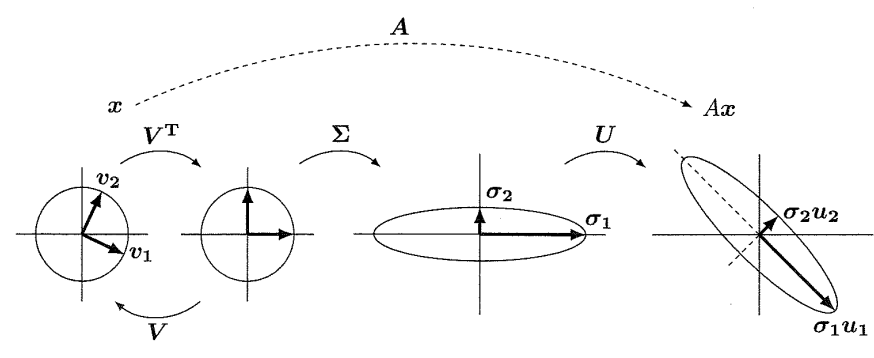

(G.Strang. Linear algebra and learning from data. MIT (2019))

Таким образом. Ортонормированные матрицы $U$ и $V$  - это операции поворота. Диагональная матрица сингулярных значений характеризует масштабирование.

Чем больше разница между сингулярными значениями, тем более вытянут эллипс


$$A=U  \Sigma V^T = \sum_{i=1}^m [\sigma_i \vec{u}_i  \vec{v}_i^T]= \sigma_1 \vec{u}_1  \vec{v}_1^T+...+\sigma_m \vec{u}_m  \vec{v}_m^T$$


, где  $\vec{u}_i$ и $\vec{v}_i$ - вектор-столбцы матриц $U$ и $V$. 

Нужно обратить внимание, что $\vec{u}_i  \vec{v}_i^T$ - это внешнее произведение, то есть матрица (рангом один) с числом строк равным числу элементов первого вектора и числом колонок равным числу элементов второго вектора. То есть, сингулярное разложение представляет матрицу как сумму матриц того же размера, при этом "вклад" каждой из этиъ матриц пропорционален сингулярному значению.

Похоже на сумму операторов проецирования, хм...

Сингулярное разложение дает два ортонормированных базиса:

$V$ - базис пространства строк

 $U$ - базис пространства столбцов

#### **Таким образом, сингулярное разложение, дает не только спектр, который характеризует степень сингулярности матрицы, но также и два ортонормированных базиса **$U$ и $V$ первый - в пространстве столбцов, а второй - в пространстве строк

#### Сингулярное разложение матриц в матлаб

% SVD разложение матрицы
clearvars
A = rand([5,3]) % матрица не квадратная, но для SVD это нормально!
[U,S,V] = svd(A)
disp("U*U'= ")
disp(U*U') % ортонормированная матрица 
norm(U) % норма ортонормированной матрицы равна единце
norm(A - U*S*V') % убеждаемся в правильности разложения
disp("A*v1:")
A*V(:,1) % действие матрицы на первый правый сингулярный вектор, дает первый левый сингулярный вектор умноженный на первое сингулярное значение
disp("u1*s1:")
U(:,1)*S(1,1)

### V) Сингулярное разложение (SVD) VS Спектральное разложение (EIG)

-  **SVD** применимо для любой матрицы, **EIG** только для квадратной

- Сингулярные значения ($\sigma_1 ... \sigma_n$) всегда положительны и действительны, собственные значения  ($\lambda_1...\lambda_n$) положительны только для положительно определенной матрицы, в общем случае, даже действительной матрицы могут "уходить" в комплексное пространство

- Сингулярные вектора $\vec{u}_1 \dots \vec{u}_n$  и $\vec{v}_1 \dots \vec{v}_n$ ортогональны и нормированы на единицу (то есть $\vec{u}_i \cdot \vec{u}_i =\vec{u}_i^T\vec{u}_i=\begin{cases} \matrix{1,i =j  \cr 0,i \neq j} \end{cases}$), то есть матрицы  $U$ и $V$ - ортонормированны. Собственные вектора $\vec{p}_1 \dots \vec{p}_n$ - не нормируются и ортогональны только для симметричной матрицы

- Сингулярные значения ($\sigma_1 ... \sigma_n$) отсортированы в порядке убывания, собственные значения ($\lambda_1...\lambda_n$) не отсортированы

- Для симметричной положительно определенной матрицы (например, такой как $C=AA^T$) , сингулярные значения равны квадратам соответсвующих собственных значений, левые и правые сингулярные вектора совпадают $V=U$, сингулярные вектора совпадают по направлению с собственными векторами 

Что быстрее SVD или EIG?

svd_test = @()svd(rand(1000));
eig_test = @()eig(rand(1000));
disp("svd_test:")
timeit(svd_test,3)
disp("eig_test:")
timeit(eig_test,3)
disp("SVD быстрее")

Действие матрицы на правый сингулярный вектор:


$$Av_1=U  \Sigma V^T\vec{v_1} = \sum_{i=1}^m [\sigma_i \vec{u}_i  \vec{v}_i^T]\vec{v_1}=\sum_{i=1}^m [\sigma_i \vec{u}_i  \vec{v}_i^T\vec{v_1}]=\sigma_1 \vec{u}_1$$


Так как : $\sigma_i \vec{u}_i  \vec{v}_i^Tv_1=\{ \matrix{1:i=1\cr 0:i\neq1}}$ вследствие ортогональности (и ортонормированности) сингулярных векторов.

clearvars
 
%M2x2 = 0.5 - rand(2)
M2x2 = [0.786,0.417;
    0.67,0.183]
[U,S,V] = svd(M2x2)
v1 =V(:,1);v2 = V(:,2);
u1 = U(:,1);u2 = U(:,2);
draw_vector([],'Сингулярные вектора',["v1" "v2" "u1" "u2"],"vector",v1,v2, u1,u2);
draw_vector([],'Действие матрицы на вектор v1', ...
    ["v1" "V'*v1-единичный вектор(орт)" "s*V'*v1 = u1!" "u1"],"vector",v1,V'*v1, S(1,1)*V'*v1,u1);
disp("|A*v1|/|u1| = " + norm(M2x2*v1)/norm(u1))
disp("S(1,1) = " + S(1,1))
draw_vector([],"Действие матрицы на систему координат" , ...
    ["v1" "v2" "A*v1 <=> u1" "A*v2 <=> u2" ], ...
    "vector",v1,v2, M2x2*v1,M2x2*v2);
disp( "Вектор-столбцы матрицы V ортогональны: v1'*v2 = " + v1'*v2)
disp( "Вектора (A*v1) и A*v2 тоже ортогональны: (A*v1)'*A*v2 = v1'*A'A*v2 = "+ transpose(M2x2*v1)*M2x2*v2)

Действие матрицы на некоторый произвольный  вектор:

Если вектор $\vec{x} $ $\in span\{V\}$, то $\vec{x}=P_{v_1}\vec{x} + ... + P_{v_m}\vec{x}=\vec{v_1}(\vec{v_1}^T\vec{x})+...+\vec{v_m}(\vec{v_m}^T\vec{x})=x_1\vec{v_1}+...x_m\vec{v_m}$ ($P_{v_i}$ - операторы проецирования)


$$A\vec{x}=U  \Sigma V^T\vec{x} = \sum_{i=1}^m [\sigma_i \vec{u}_i  \vec{v}_i^T][ \sum_{i=1}^m [ x_1\vec{v_1}+...x_m\vec{v_m}]=\sum_{i=1}^m [\sigma_i x_i \vec{u}_i  ]$$


Так как : $\sigma_i \vec{u}_i  \vec{v}_i^Tv_1=\{ \matrix{1:i=1\cr 0:i\neq1}}$ вследствие ортогональности (и ортонормированности) сингулярных векторов.

R =[75.957;1]
ang = deg2rad(R(1)); %угол вектора
module = R(2);% модуль вектора
x = [module*cos(ang);module*sin(ang)];
%draw_vector("Действие матрицы на произвольный вектор",["x" "v1" "v2" "u1" "u2" "V'*x" "S*V'*x" "U*S*V'*x <=> A*x"],x,v1,v2,u1,u2,v'*x, s*v'*x,u*s*v'*x);
draw_vector([],"Действие матрицы на произвольный вектор",["x" "v1" "v2" "u1" "u2" ...
    "U*S*V'*x <=> A*x"],"vector",x,v1,v2,u1,u2,U*S*V'*x);
cos_alfa = transpose(U*S*V'*x)*x;
cos_alfa = cos_alfa/(norm(U*S*V'*x)*norm(x));
disp("Скалярное произведение acos(alfa) = acos((x'*Ax)/(|x|*|Ax|)) = " + rad2deg(acos(cos_alfa)))

clearvars
% матрица диагональная
A = diag(rand(5,1))
svds(A)
% матрица c большой асимметрией
A = eye(5);
A(5) = 1e6
S = svds(A)
% Последнее сингулярное значение близко к нулю, почему так?

#### Немного  теорвера и матстата

У нас есть случаная переменная, которая может принимать некоторый (дискретный) набор возможных значений:


$$x \sim x_1 \dots x_N$$
 

Вероятноятность переменной иметь некоторое определенноей значение из этого дискретного набора характеризуется набором вероятностей:

$P \sim p_1 \dots p_N$, $\Sigma_ip_i=1$

Для некоторой случайно впеременной, которая получается из некоторого распределения $P$, математическое ожидание будет:


$$m=\mathbb{E}(x\sim P)=\Sigma_ip_ix_i$$


Среднее значение результатов набора из $M$ испытаний:

$\mu=\frac{\Sigma_{j=1}^Mx_j} {M}$ - применяется для экспериментальной оценки мат. ожидания.

Разброс данных характеризуется вариацией:


$$\nu=\mathbb{E}[(x-m)^2]=\Sigma_ip_i(x_i-m)^2$$


Для экспериментальной оценки вариации:


$$\sigma= \frac {\Sigma_{j=1}^M(x_j-\mu)^2} {M-1}$$


Если случаная величина характеризуется векторов, то есть состояний несколько, например, $[\matrix {x \cr y}]$, каждая из компонент идет из своего распределения, то :


$$\sigma_x= \frac {\Sigma_{j=1}^M(x_j-\mu_x)^2} {M-1}, \sigma_y= \frac {\Sigma_{j=1}^M(y_j-\mu_y)^2} {M-1}$$


Если есть две переменных, то появляется ковариация, которая характеризуется совместной вероятностью события с вектором состояний $[\matrix {x_i \cr y_j}]$.


$$\nu=\mathbb{E}[(x-\mathbb{E}[x])(y-\mathbb{E}[y])]=\Sigma_{ik}p_{ik}(x_i-m_x)(y_k-m_y)$$


$p_{ik}$ - совместная вероятность 

#### Матрица ковариации:

$\vec{X_1}...\vec{X_m}...\vec{X_M}$ - вектора результатов испытания (определения $N$ свойств)  "образца" размером $N \times 1
$ каждый (вектора состояния некоторого случайного процесса). 

$M$ - число испытаний, $N$ - число свойств ($N<M$)

$\vec{\mu} = \mu_1 ... \mu_n ... \mu_N$ - средние  значения по всем испытаниям для каждого из свойств: $\mu_n=\frac{\sum_{i=1}^{M} x_{ni}} {M}$

clearvars
x1 = sym("x1",[2 1])
x2 = sym("x2",[2 1])
x3 = sym("x3",[2 1])
mu = sym("mu",[2,1])
% три измерения двух свойств N = 2, M = 3

Матрица матрица испытаний $[N\times M]$:

$A = [\vec{X_1}-\vec{\mu},{...},\vec{X_m}-\vec{\mu},{...},\vec{X_N}-\vec{\mu}]$ - каждый столбец - вектор результатов измерений (вектор состояния), смещенный на среднее значение ($[{...}]$ - операция конкатенации)

A = [x1-mu,x2-mu,x3-mu]

Экспериментальная оценка матрицы ковариации (симметричная матрица размером $N \times N$):

$C =\frac {A A^T} {(M-1)}$                                                                                                                                 (3)

C = A*transpose(A)*sym("1/2")

Диагональные элементы матрицы $C_{nn}$- коэффициенты вариации ($n=1{...}N$),  для  $n$ - го  свойства : $C_{nn}=\frac {\sum_{i=1}^{M}(x_{ni}-\mu_n)^2}{M-1}$  

Если из диагональных элементов извлечь корень и поделить на количество экспериментов $L$, то получим стандартное отклонение среднего арифметического.

Элементы матрицы $C$, стоящие вне диагонали, -  коэффициенты ковариации   $n$ - го  и $m$ - го свойств: $C_{nk}=\frac {\sum_{i=1}^{M}[ (x_{ni}-\mu_n)(x_{ki}-\mu_k)]} {M-1}$ ($n,k=1{...}N , n \not = k$) 

Эти формулы понятнее, если посмотреть не на матрицу $A$, на транспонированную матрицу $B=A^T$, в матрице $B$, каждый столбец ($\vec{b}_n$), размером $[M \times 1]$  будет соответствовать какому-то свойству, измеренному $M$ раз. Тогда вектор средних $\vec{\mu}$ - это вектор средних значений по каждому из столбцов. 

То есть, хотя табличка данных одна и та же в зависимости от того как на нее смотреть ее интерпретация различна: 

матрица $A$ - это набор испытаний, в каждом из которых был определен некоторый набор свойств, 

матрица $B=A^T$ - это набор свойств, для каждого из которых было выполнено некоторое число испытаний.

B = transpose(A)
b1 = B(:,1)
b2 = B(:,2)

 В соответствии с (3), матрица ковариации через матрицу свойств $B$ выражается в виде: 

$C = A A^T/(M-1)= B^T  B/(M-1)$                                                                                                                                 (4)

То есть, диагональные элементы матрицы ковариации (вариация) $C_{nn}=\frac {\vec{b}_n^T  \vec{b}_n} {M-1}$ - это просто скалярное произведение столбца матрицы $B$ самого на себя, а элементы, стоящие вне диагонали - это скалярные произведения различных столбцов матрицы $B$:  $C_{nk}=\frac {\vec{b}_n^T\vec{b}_k} {M-1}$ скалярное произведение двух векторов характеризует то насколько один вектор "отстоит" от другого, по сути это проекция одного вектора на другой. Если оба вектора единичные по амплитуде, то это косинус угла между ними. Если скалярное произведение равно нулю, то вектора сонаправлены, то есть максимально "зависимы".

C_b = transpose(B)*B

#### Спектральное разложение матрицы ковариации <=> сингулярное разложение матрицы измерений:

Пусть матрица измерений $A$ имеет следующее сингулярное разложение:


$$A=U \Sigma V^T$$
 

 Тогда матрица ковариации может быть представлена в виде:

$C = A A^T = (U \Sigma  V^T) (U \Sigma  V^T) ^T =  (U \Sigma V^T) (V  \Sigma U^T)  =  U \Sigma^2  U^T$                                                                                                                     (5)


$$C = U \Sigma^2  U^T=U \Sigma^2  U^{-1}$$
  

$C  =P  \Lambda  P^{-1}$ - спектральное разложение матрицы ковариации 

Столбцы матрицы собственных векторов не ортонормированы, однако, для симметричной положительно определенной матрицы $C$, которой является матрица ковариации, они ортогональны, то есть: $P^{-1}=P^T$, таким образом, левые сингулярные вектора матрицы испытаний есть нормированные собственные вектора матрицы ковариации, а собственные значения - квадраты сингулярных значений.

#### Пример корреляции при бросании двух монеток.

Испытание - однократное бросание двух монеток (вектор состояния системы из двух монеток -1/2 - решка, +1/2 - орел). 

Свойство - состояние одной монетки.

Если монетки некоррелированы, то в каждом испытании состояние каждой из монет не зависит от состояния другой.

Монетки максимально коррелированы, когда одна приклеена к другой.:

clearvars
points_number = 500; % число бросаний
% монетки независимы друг от друга
first_coin = (rand(points_number,1)>=0.5) - 0.5; % +-1/2 орел/решка, среднее - ноль
second_coin = (rand(points_number,1)>=0.5) -0.5;
disp("Матрица испытаний для независимых монет: ")
A = transpose([first_coin-mean(first_coin),second_coin-mean(second_coin)]) % матрица испытаний
disp("Матрица свойств: ")
B = A' % матрица свойтсв
ncorrelated_coins_covariance_matrix = transpose([first_coin,second_coin])*[first_coin,second_coin]/(points_number-1);
disp("Монетки бросаются независимо друг от друга:")
disp(ncorrelated_coins_covariance_matrix)
disp("Матрица ковариации близка к диагональной - максимально несингулярна, колонки полностью независимы")
% монетки приклеены друг к другу одноименными концами
first_coin_dependent = (rand(points_number,1)>=0.5) - 0.5;
first_coin_dependent = first_coin_dependent-mean(first_coin_dependent);
disp("Матрица испытаний для склееных монет: ")
transpose([first_coin_dependent,first_coin_dependent]) % матрица испытаний

correlated_coins_covariance_matrix = transpose([first_coin_dependent,first_coin_dependent])*[first_coin_dependent,first_coin_dependent]/(points_number-1);
disp("Монетки склеены одноименными концами, матрица ковариации:")
disp(correlated_coins_covariance_matrix)
disp("Матрица ковариации сингулярна, так как колонки одинаковы, то есть линейно зависимы")
[U,S,V] = svd(A)
[Q,L] = eig(A*A')

## Примеры использования 

### Пример использования  - детерминированные данные: колебание грузика на пружине и два датчика

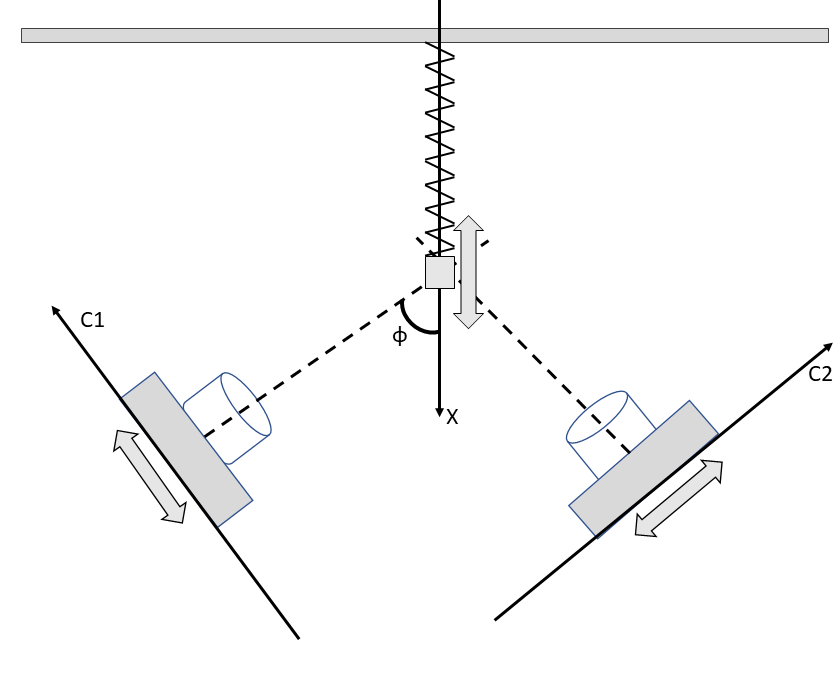

clearvars
t = linspace(-pi,pi,100) % фаза движения 
X = cos(t) % закон движения грузика на пружине
phi = 30; % угол ориентации камер относительно оси колебания грузика
c1 = X*cosd(phi); % показания камеры 1
c2=X*sind(phi); % показания камеры 2
A=[c1;c2] % матрица эксперимента 
scatter(c2,c1);
xlabel("Показания первого датчика")
ylabel("Показания второго датчика")
[V,S,U] = svd(A) % считаем сингулярное разложение
% спектр сингулярных значений состоит из одного значения, это значит, что
% нам достаточно одного датчика!
cosd(phi) % косинус угла ориентации датчиков
sind(phi) % синус угла ориентации датчиков
V2 = [cosd(phi) sind(phi);...
     sind(phi) -cosd(phi)] % матрица вращения на угол фи в двумерном пространстве
% Таким образом, V - матрица поворота
rad2deg(subspace(A,[1;0])) % угол между подпространством матрицы измерений единичным вектором (вектор X рисунке), так как матрица 
% A - сингулярна (измерения полностью коррелированы), ее подпространство
% состоит из одного вектора, поэтому углом между поодпространством ее
% столбцов и вектором будет угол фи
disp("Матрица ковариации:")
C = A*A'/(numel(t)-1)

#### Пример использования: "случаные" данные

#### Генерация исходных данных по трем свойствам (два из них - коррелированы)

clearvars
rand_fun = "randn"; % выбираем статистику из которой набираются "экспериментальные точки" randn - Гауссово распределение, rand - равномерное распределение от 0 до 1
rand_fun_handle = str2func(rand_fun); % форма распределения
points_number = 90; % число экспериментальных точек
X = 60 + rand_fun_handle(points_number,1); % генерим массив случайных точек (результаты измерения первого параметра)
Y = 1.26+ 0.1*rand_fun_handle(points_number,1); % генерим массив случайных точек (результаты измерения второго параметра) полностью случайны, не зависят от X
alfa_cor =0.75;
Ycor = 3 + (alfa_cor*X + (1-alfa_cor)*rand_fun_handle(points_number,1));% Ycor - коррелирует с X
disp("Матрица свойств:")

Матрица свойств:


t1 = table(X,Y,Ycor,'VariableNames',["Прочность" "Теплопроводность" "Диэлектрическая проницаемость"]);
disp(t1)

    Прочность    Теплопроводность    Диэлектрическая проницаемость
    _________    ________________    _____________________________

     60.463            1.129                    48.771            
     61.186           1.1324                    48.993            
     60.311           1.2759                    47.923            
     60.022           1.1879                     48.04            
     59.184           1.3215                    47.306            
     60.289           1.2836                    47.787            
     59.589           1.3194                    47.668            
      58.51           1.1056                    46.728            
     61.448           1.4063                     49.27            
      59.63           1.1714                    48.072            
     61.071           1.0676                    48.914            
     60.087           1.21

disp("Матрица испытаний:")

Матрица испытаний:


disp([X';Y';Ycor'])

   60.4635   61.1860   60.3115   60.0224   59.1840   60.2890   59.5885   58.5102   61.4476   59.6304   61.0709   60.0873   59.2509   61.1046   59.8490   59.9298   62.4741   59.5313   60.0586   60.3442   59.5489   60.6247   60.8826   60.0249   61.8178   59.7220   60.3412   60.2089   61.3282   59.0261   62.3181   60.2171   58.3518   59.5599   60.7988   60.1118   60.7532   57.3990   58.7810   60.7923   60.7643   59.5796   60.4658   58.6104   60.4723   58.6523   59.8893   60.8688   61.0989   58.8524   59.9717   60.1763   59.6625   59.7683   60.0740   61.8074   58.8943   60.7495   60.9299   60.0269   61.6234   61.0376   60.5521   59.7139   59.0439   60.6318   60.8907   60.2764   57.9468   60.6085   56.5854   58.9974   59.0816   58.9810   59.9333   59.9432   60.1212   57.8339   59.9569   59.9014   59.1327   59.1787   59.8447   59.5195   59.4581   57.9290   58.7229   59.9939   61.0671   61.3925
    1.1290    1.1324    1.2759    1.1879    1.3215    1.2836    1.3194    1.1056    1.4063    1.171

% СЧИТАЕМ СРЕДНИЕ И НОРМИРУЕМ 

Xn = (X-mean(X)); % смещаем среднее для первого свойства
Yn = (Y - mean(Y));% смещаем среднее для второго свойсва
Ycorn = ((Ycor - mean(Ycor))); % нормированные данные

% вначале рассмотрим матрицы 2х2
A2 = transpose([Xn,Yn]); % матрица испытаний для некоррелированных параметров (два параметра)
A2cor = transpose([Xn,Ycorn]); % матрица испытаний для коррелированных параметров (два параметра)
A3 = transpose([Xn,Yn,Ycorn]); % матрица испытаний для всех трех свойств
covMATuncor = A2*transpose(A2)/(points_number-1); % матрица ковариации для некоррелированных данных
covMATcor =  A2cor*transpose(A2cor)/(points_number-1);% матрица ковариации для коррелированных данных
covMAT3 = A3*transpose(A3)/(points_number-1);
disp("Матрица ковариации независимых друг от друга данных:")

Матрица ковариации независимых друг от друга данных:


disp(covMATuncor)

    1.1012   -0.0045
   -0.0045    0.0123



disp("Матрица ковариации взаимосвязанных данных Y="+alfa_cor+"*X +"+(1-alfa_cor)+"*rand")

Матрица ковариации взаимосвязанных данных Y=0.75*X +0.25*rand


disp(covMATcor)

    1.1012    0.8548
    0.8548    0.7164



disp("Матрица ковариации для трех параметров {X=rand,rand,Y="+alfa_cor+"*X +"+(1-alfa_cor)+"*rand}")

Матрица ковариации для трех параметров {X=rand,rand,Y=0.75*X +0.25*rand}


disp(covMAT3)

    1.1012   -0.0045    0.8548
   -0.0045    0.0123   -0.0029
    0.8548   -0.0029    0.7164



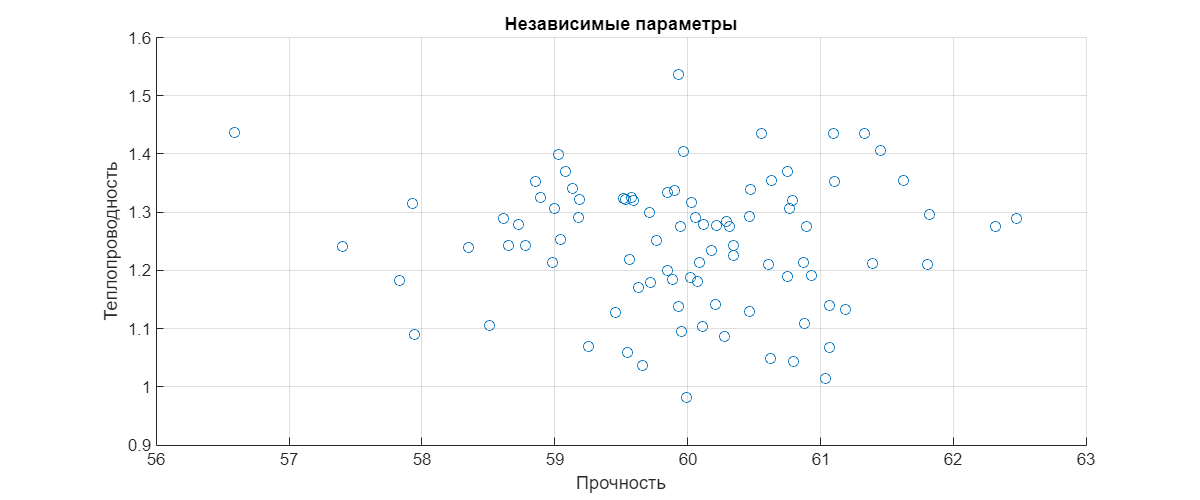


scatter(t1.("Прочность"),t1.("Теплопроводность"));
xlabel(t1.Properties.VariableNames{1});
ylabel(t1.Properties.VariableNames{2});
title("Независимые параметры")
grid on 

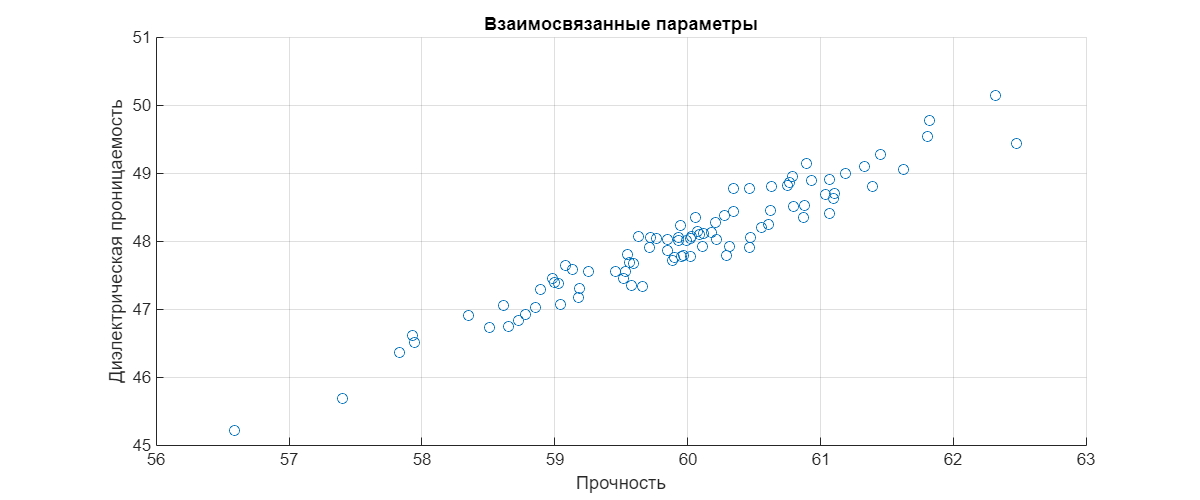

scatter(t1.("Прочность"),t1.("Диэлектрическая проницаемость"));
xlabel(t1.Properties.VariableNames{1});
ylabel(t1.Properties.VariableNames{3});
title("Взаимосвязанные параметры")
grid on 

Собственные значения и собственные вектора матрицы ковариации:

[Q,L] = eig(covMATcor,'vector')

Q =     0.6247   -0.7809
   -0.7809   -0.6247


L =     0.0326
    1.7850


ax = draw_vector([],"Scattered data","","point",A2cor(1,:),A2cor(2,:));

fig1


draw_vector(ax,"Собственные вектора матрицы ковариации","","vector",Q(:,1),Q(:,2))

ans =   Axes (Собственные вектора матрицы ковариации) with properties:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


[U,S,V] = svd(A2cor) % SVD разложение

U =    -0.7809    0.6247
   -0.6247   -0.7809


S =    12.6041         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.7025         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

V =    -0.0686   -0.1799   -0.0236   -0.0047    0.0814   -0.0178    0.0396    0.1504   -0.1507    0.0245   -0.1112   -0.0114    0.0690   -0.1075    0.0138    0.0034   -0.2350    0.0475   -0.0166   -0.0510    0.0387   -0.0633   -0.0853    0.0027   -0.1942    0.0179   -0.0409   -0.0261   -0.1366    0.0913   -0.2436   -0.0195    0.1571    0.0414   -0.0783   -0.0081   -0.0840    0.2668    0.1237   -0.0909   -0.0862    0.0498   -0.0352    0.1329   -0.0398    0.1390    0.0152   -0.0790   -0.1048    0.1154
   -0.1244   -0.0169    0.1537   -0.0069    0.0265    0.2085    0.0067    0.0480   -0.0553   -0.1656   -0.0282   -0.0093   -0.0637    0.0835    0.0106   -0.0251    0.2395    0.0401   -0.1367   -0.2281   -0.0702    0.0215    0.0834    0.1142   -0.1553   -0.1244   -0.0728   -0.0481   -0.0212   -0.0679   -0.1442    0.0680   -0.0959   -0.0105    0.0602    0.0812   -0.1021    0.1270    0.0561   -0.1492   -0.1182    0.1524    0.2141   -0.0685    0.1509    0.0928    0.0972    0.1612    0.1169    0

I = ones(size(A2cor,2),1);
% если данные линейно коррелированы, почему бы не попробовать зафитить их
% полиномом первой степени 
% A2cor(2,:) = lsqr_fit(1) + lsqr_fit(2)*A2cor(1,:)
vandermonde_matrix = [I A2cor(1,:)'] % матрица Вадермонда (что это?)

vandermonde_matrix =     1.0000    0.4839
    1.0000    1.2064
    1.0000    0.3320
    1.0000    0.0428
    1.0000   -0.7956
    1.0000    0.3095
    1.0000   -0.3910
    1.0000   -1.4693
    1.0000    1.4681
    1.0000   -0.3492


lsqr_fit = atan(vandermonde_matrix\A2cor(2,:)') % решаем задачу метода наименьших квадратов (

lsqr_fit =    -0.0000
    0.6601


a_lsqrt = [cos(lsqr_fit(2));sin(lsqr_fit(2))]

a_lsqrt =     0.7899
    0.6132


draw_vector(ax,"Собственные вектора матрицы ковариации и сингулярные вектора матрицы испытаний",["u1" "u2"],"vector",U(:,1),U(:,2)*S(2,2)/S(1,1),a_lsqrt)

ans =   Axes (Собственные вектора матрицы ковариации и сингулярные вектора матрицы испытаний) with properties:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


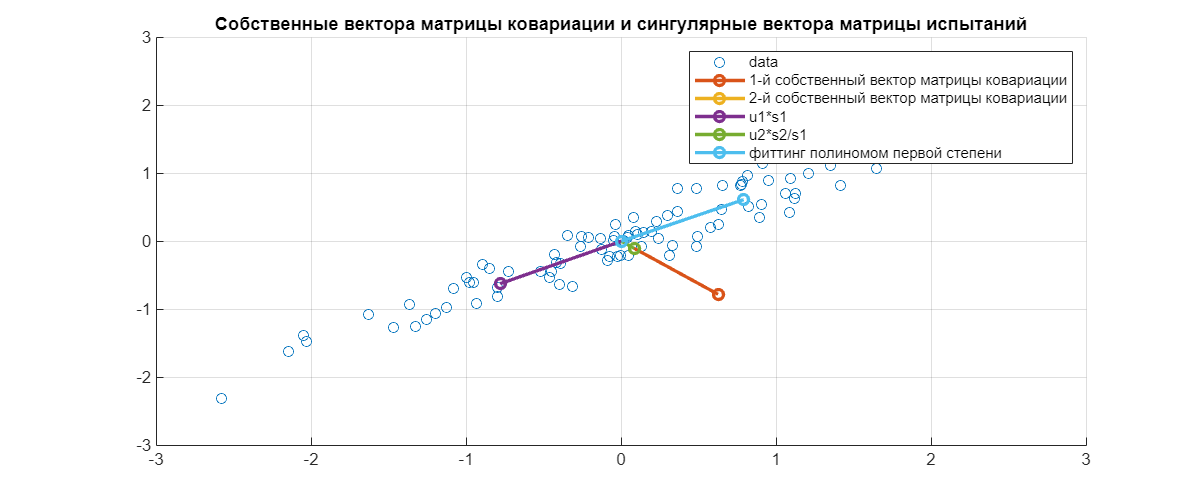

xlim(ax,[-3,3])
ylim(ax,[-3,3])
legend(ax,["data" "1-й собственный вектор матрицы ковариации" ...
    "2-й собственный вектор матрицы ковариации" "u1*s1" "u2*s2/s1" "фиттинг полиномом первой степени "])

% transpose(Q)*U
disp("Матрица сингулярных значений матрицы испытаний (в квадрате и нормированы на (1-N)):")

Матрица сингулярных значений матрицы испытаний (в квадрате и нормированы на (1-N)):


(S.^2)/(points_number-1)

ans =     1.7850         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0326         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

disp(" Матрица собственных значений матрицы ковариации : ")

 Матрица собственных значений матрицы ковариации : 


diag(eig(covMATcor))

ans =     0.0326         0
         0    1.7850


Таким образом, правые сингулярные вектора дают направление векторов вдоль главных осей эллипса. Таким образом , что максимальная вариация данных (главная ось эллипса) проиходит вдоль главной оси эллписа, которая соответсвует первому сингулярному вектору.

Проекция столбцов матрицы $A$ на вектор $\vec{u_1}$:


$$\vec{u}_1^TA=\vec{u}_1^TU  \Sigma V^T = \vec{u}_1^T\sum_{i=1}^m [\sigma_i \vec{u}_i  \vec{v}_i^T]=  \sigma_1  \vec{v}_1^T$$


Амплитуда суммы проекций столбцов матрицы это длина этого вектора:


$$||\vec{u}_1^TA||= || \sigma_1  \vec{v}_1^T||=\sigma_1$$


Направление первого левого сингулярного вектора показывает вектор, сумма проекций векторов состояния (столбцы матрицы измерений) на который максимальна!

Разница между методом наименьших квадратов и сингулярным разложением показана на рисунке: 

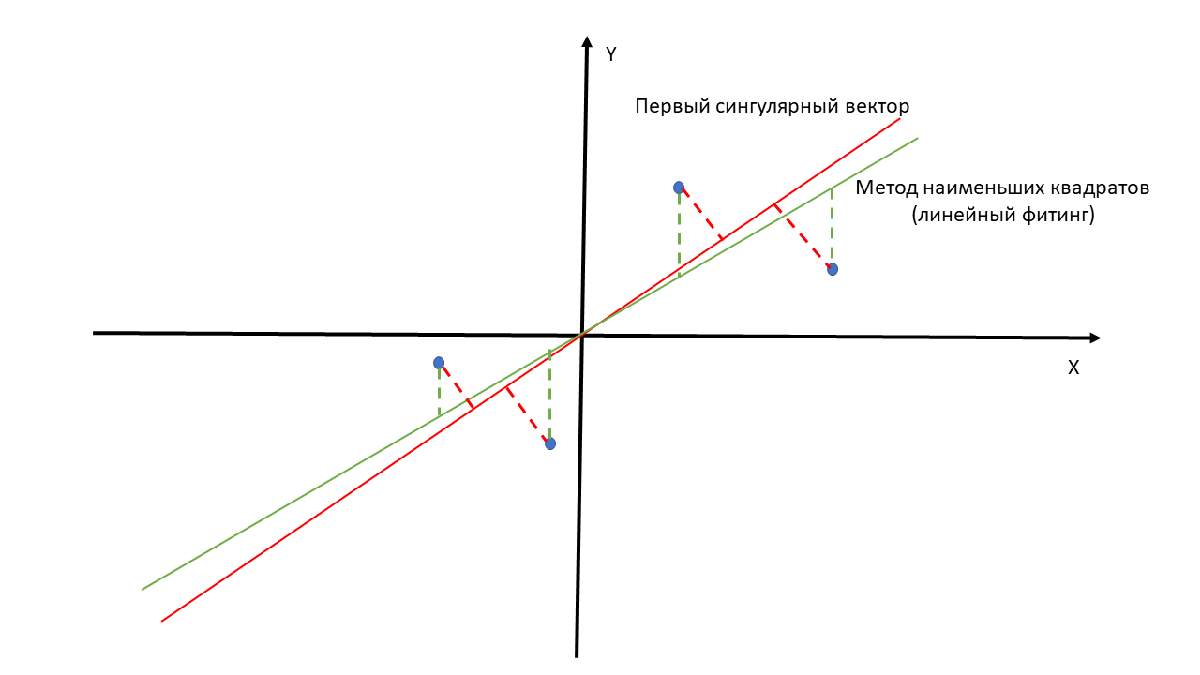

Линейная алгебра  построена так, чтобы она без проблемы экстраполировалась на пространства б**о**льшей размерности.

Три ... 

covMAT3
%ax2 = draw_vector([],"Scattered data","","point",A3(1,:),A3(2,:),A3(3,:));
[U,S,V] = svd(A3)
U(:,3)'*U(:,2)

ax2 =draw_vector([],"Scattered data","","vector",U(:,1),U(:,2),U(:,3));
draw_vector(ax2,"Scattered data","","point",A3(1,:),A3(2,:),A3(3,:));
xlim(ax2,[-3,3]);
ylim(ax2,[-3,3]);
legend(ax2,["data" "u1*s1" "u2*s2/s1" "u3*s3/s1"]);

Пять...

clearvars -except points_number rand_fun_handle alfa_cor
X1 = randn(points_number,1);
X2 = randn(points_number,1);
X3 = randn(points_number,1);
alfas1 = [0.01,0.01,0.07];
alfas2 = [0,0,0.08];
alfas2 = alfas2/sum(alfas2);alfas1 = alfas1/sum(alfas1);

X4 = (1-alfa_cor)*rand_fun_handle(points_number,1) + alfa_cor*sum([X1,X2,X3].*alfas1,2);
X5 = (1-alfa_cor)*rand_fun_handle(points_number,1) + alfa_cor*sum([X1,X2,X3].*alfas2,2);

C = transpose([X1,X2,X3,X4,X5])*[X1,X2,X3,X4,X5]/(points_number-1)

SIG = svds(C)/(points_number-1)

# ВЫВОД:

## Метод анализа главный компонент позволяет установить насколько коррелированы исходные данные, а также дает линейное преобразование исходных данных в "новые", в которых базис соответствует собственным векторам матрицы ковариации.

$M$ - матрица эксперимента

S = svds(M,N) - первые N ее сингулярных значений, чем ближе они друг к другу, тем более некоррелированными являются колонки в таблице 

# Литература

- Gilbert Strang. Linear algebra and learning from data. MIT (2019)

- Gilbert Strang. Introduction to linear algebra. 2016 (Есть перевод старой версии книги : Г.Стрэнг Введение в линейную алгебру)

- youtube: канал  MIT OpenСourseWare, курс лекций MIT: 18.06SC Linear Algebra (2011)

- youtube: канал  MIT OpenСourseWare, курс лекций: MIT 18.065 Matrix methods in Data Analysis, Signal processing, and Mechine Learning (2018)

- youtube: канал AMATH 301, лектор  Nathan Kutz, лекции: The singular Value Decomposition and Principal Componen Analysis

## BONUS с картинками!

#### Теорема Экхарта-Янга:

Пусть $A_k =  \sum_{i=1}^k [\sigma_i  \vec{u}_i \vec{v}_i^T]$, где $\forall $ $k\le m$, тогда для $\forall $ матрицы $B$ ранга $k$:  $||A-B||\ge||A-A_k||$.

Иными словами, матрица $A_k$ является наилучшей аппроксимацией матрицы $A$ среди всех матриц ранга $k$.

Картинка  - это же матрица!

clearvars
% Import image
folder =  get_folder()
full_file = folder + "\figs\figs.png"
figs = imread(full_file);

% Display results
imshow(figs);
title("Image Data from figs.png");

 
A = double((im2gray(figs))); 
[U,S,V] = svd(A);% сингулярное разложение исходной картинки

folder = 'D:\Program Files\matlab files\matlab-seminar\examples\PCA'

number_of_dimentions=1;

full_file = "D:\Program Files\matlab files\matlab-seminar\examples\PCA\figs\figs.png"

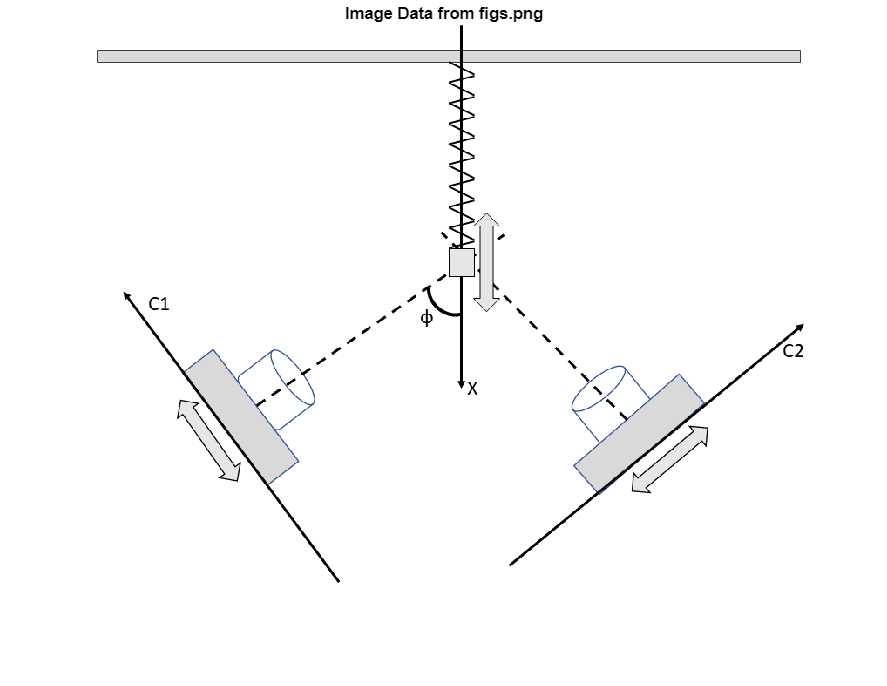

if number_of_dimentions>size(U,2)
    number_of_dimentions = size(U,2);
end
% уменьшаем размерность исходной картинки
Uk = U(:,1:number_of_dimentions);

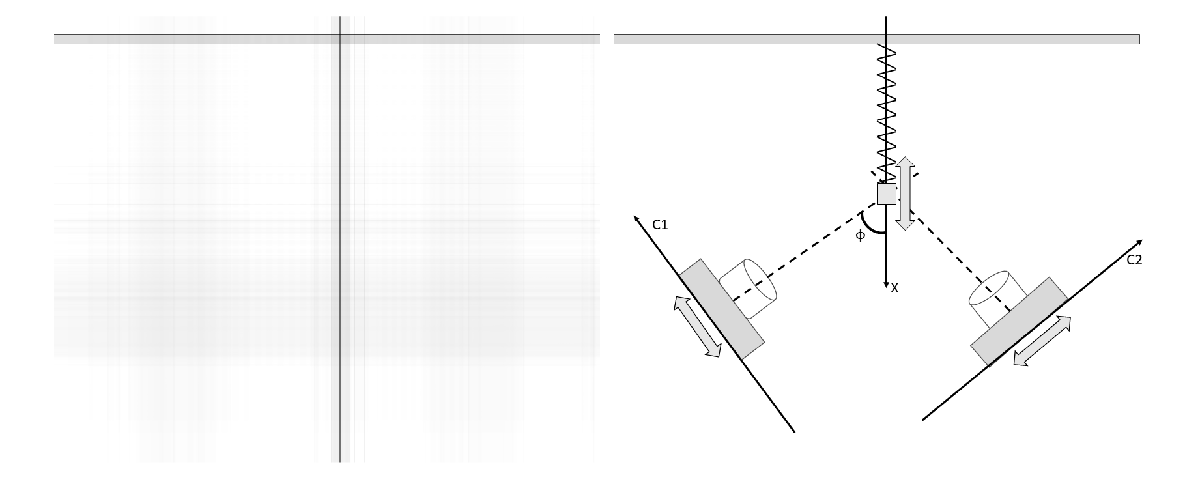

Sk = diag(S(1:number_of_dimentions,1:number_of_dimentions));
Vk = V(:,1:number_of_dimentions);
Ak = Uk.*Sk'*Vk'; % матрица уменьшенной размерности 
imshow(uint8([Ak,A]))
display("Ранг исходной картинки:" + rank(A))
display("Ранг сжатой картинки:" + rank(Ak))
wA  = mem_size_summ("A") ;% объем памяти в байтах,занимаемой исходной матрицей
wAk = mem_size_summ("Uk","Sk","Vk") ; % объем памяти в байтах
disp("Объем исходной матрицы в байтах :"+ wA)
disp("Объем сжатой матрицы  в байтах :"+wAk)

disp("Относительный объем памяти сжатый/несжатый:"+ wAk/wA)
ax = get_next_ax();
plot(ax,1:size(S,2),log(sum(S)),'ob',1:number_of_dimentions,log(Sk),'*r')
title(ax,"Спектр сингулярных значений матрицы");
xlabel(ax,"Порядковый номер");

ylabel(ax,"log(\sigma_n)");

    "Ранг исходной картинки:415"



legend(ax,["Исходная матрица" " Матрица уменьшенной размерности"]);

    "Ранг сжатой картинки:1"



path = "D:\mironov\matlab projects\Presentations\MATLAB seminar\";
svd_struct(10) = struct("V",[],"S",[],"U",[],"M",[])

Объем исходной матрицы в байтах :4592240


for ii=0:9

Объем сжатой матрицы  в байтах :12192


    cur_im = imread(fullfile(path,ii+".png"));
    mat = double((im2gray(cur_im)));

Относительный объем памяти сжатый/несжатый:0.0026549


    i = ii +1;

fig2


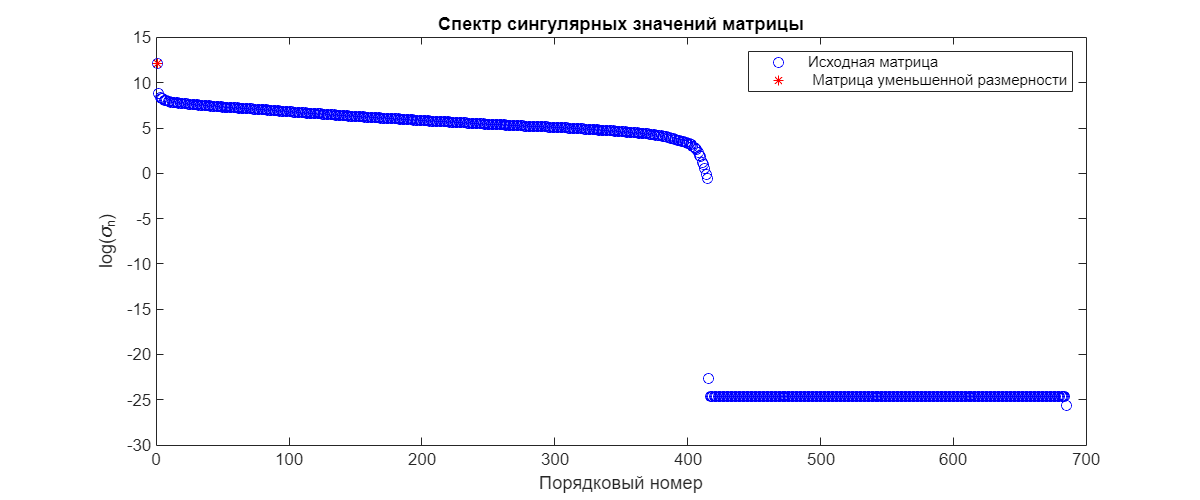

    svd_struct(i).M = (mat);
    [svd_struct(i).V,svd_struct(i).S,svd_struct(i).U] = svd(mat);
end
imshow(uint8([svd_struct(:).M]))
ranks = arrayfun(@(X)rank(X.M),svd_struct)

sig_mat = ones(size(mat,1),10); % матрица спектров сингулярных значений
for iii = 1:numel(svd_struct)
    sig_mat(:,iii) = sum(svd_struct(iii).S);
end
p = plot(get_next_ax(),log(sig_mat), 'LineWidth',3,'MarkerSize',6)
ylim([-1,10])
legend(string(0:9) + " rank=" + string(ranks),'FontSize',12)
mark = ["+","o","*",".","square","diamond","v","^","pentagram","hexagram"];
arrayfun(@(ii)set(p(ii),"Marker",mark(ii)),1:10)
title("Спектр сингулярных значений циферок");
xlabel("Порядковый номер");
ylabel("log(\sigma_n)");

function ax = draw_vector(ax,ttl,names,type,varargin)
% функция строит двух- и трех-мерные вектора, а также рассеянные данные из
% матрицы
% ax - оси (если пустые, то создаются новые)
% ttl - заголовок картинки
% names - имена векторов
% type:
%       "vector" - аргументы, которые передаются после интерпретируются
%                   как отдельные вектора
%       "point"  - в этом случае передается матрица в качестве аргумента и
%       столбцы матрицы строятся при помощи функций scatter и scatter3 d
%       в зависимости от размерности массива
    arguments
        ax =[]
        ttl string =strings(0,1)
        names string =strings(0,1)
        type string {mustBeMember(type,["vector" "point"])}="vector"
    end
    arguments (Repeating)
        varargin double
    end
    was_empty = isempty(ax); % это признак того, что все строится на новых осях
    if was_empty
        ax = get_next_ax();
    else
        hold(ax,"on");
        % if ~isempty(ax.Legend)
        %     leg_before = ax.Legend.String;
        % else
        %     leg_before = strings(0,1);
        % end
    end
    
    if strcmp(type,"vector")
        is_3D = numel(varargin{1})==3;
            if is_3D
                [x,y,z]  = make_xy(varargin{1});
                plot3(ax,x,y,z,'LineWidth',2,'Marker','o');
                hold on 
                for iii = 2:numel(varargin)
                        [x,y,z] = make_xy(varargin{iii});
                        plot3(ax,x,y,z,'LineWidth',2,'Marker','o');
                end
                grid on
                hold off                
            else
                [x,y]  = make_xy(varargin{1});
                plot(ax,x,y,'LineWidth',2,'Marker','o');
                hold on 
                for iii = 2:numel(varargin)
                        [x,y]  = make_xy(varargin{iii});
                        plot(ax,x,y,'LineWidth',2,'Marker','o');
                end
                grid on
                hold off
            end
            if isempty(names)||(numel(names)~=numel(varargin))
                legend(ax,string(1:numel(varargin)));
                
            else
                % if ~was_empty
                %      names= [names(:);leg_before(:)];
                % end
                legend(ax,names);
            end
            xlim(ax,[-1 1]);
            ylim(ax,[-1 1]);
            if ~isempty(ttl)
                title(ax,ttl);
            end
    else
        %data_number = numel(varargin); % число массивов данных
        is_3D = numel(varargin)==3;
        data = varargin{1};
        if size(data,2)>1
            data = transpose(data);
            is_transpose = true;
        else
            is_transpose = false;
        end
        if ~is_transpose
            for iii = 2:numel(varargin)
                data = [data,varargin{iii}];
            end
        else
            for iii = 2:numel(varargin)
                data = [data,transpose(varargin{iii})];
            end            
        end

        if is_3D
            scatter3(ax,data(:,1),data(:,2),data(:,3));
        else
            scatter(ax,data(:,1),data(:,2));
        end

    end
    if ~was_empty
            hold(ax,"off");
    end
end
function [x,y,z]  = make_xy(col)
% добавляет к координатам вектора нули так, чтобы при помощи функции plot
% строилась линия
    switch numel(col)
        case 1
            x = [col(1)];
            y = 0;
            z = 0;
        case 2
            x = [0 col(1)];
            y = [0 col(2)];
            z = zeros(1,2);
        case 3
            x = [0 col(1)];
            y = [0 col(2)];
            z = [0 col(3)];
    end
end
function [bpar,bper,ang] = projection_matrix(A,b)
% функция считает угол между вектором и пространством столбцов матрицы A
    for ii =1:size(A,2)
        A(:,ii) = A(:,ii)/norm(A(:,ii));
    end
    beta = A*transpose(A)*b;
    beta = beta/norm(beta); % нормируем вектор beta
    Pbeta = beta*transpose(beta); % оператор проектирования вектора на 
    bpar = Pbeta*b;
    bper = b-bpar;
    ang = rad2deg(acos(norm(bpar)/norm(b)));
end
function [new_ax,fig_handle] = get_next_ax(index)
% функция, которая возвращает новые оси на новой фигуре
    arguments
        index = []
    end
    persistent N;
    if isempty(index)
        if isempty(N)
            N=1;
        else
            N  = N+1;
        end
        fig_handle = figure(N);
        clf(fig_handle);
        new_ax = axes(fig_handle);
        disp("fig"+ N)
    else
        fig_handle = figure(index);
        clf(fig_handle);
        new_ax = axes(fig_handle);    
    end
end
function mem_size = mem_size_summ(varargin)
% функция считает объем несокльких переменных в памяти base workspace
    names = string(varargin);
    mem_size = 0;
    base_vars = evalin("base","whos");
    flag = arrayfun(@(X)any(strcmp(X.name,names)),base_vars);
    if ~any(flag)
        return
    end
    mem_size = sum(arrayfun(@(X)X.bytes,base_vars(flag)));
end
function folder = get_folder()
% текущая папка
folder = fileparts(matlab.desktop.editor.getActiveFilename);
end